# Pressure & Velocity

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

In fluid dynamics, understanding the link in between pressure, velocity, energy and power is essential because they are the driving mechanism of fluid flow. Pressure is closely relate to the forces exherted by the fluid, velocity measure the speed and direction of the fluid, energy is a measure of the ability of a fluid to do work, and power is a measure of the rate at which energy is transfered. In this script we will explore how these concept are related, interact and how critical they are in the design and analysis of fluid systems such as pumps, pipelines, and hydroelectric power plants.

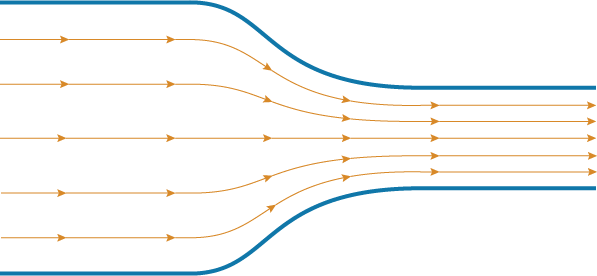

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is pressure?

Pressure is a measure of the force that a fluid exert on the wall of container. On a microscopic scale, the fluid particles are impacting the container wall and bounce back from it. Because the fluid is composed of a very large number of particle, all of those discrete impact can be added together over time. The resulting force from this very large number of impacts the pressure, often noted $p$ or $P$. Pressure is a scalar quatity that exist in the whole fluid domain, it is dimensionally equivalent to a force per unit of surface. The total resulting force on a surface can be calculated from the pressure by using the following formula:


$$F=P\times S$$


  **Try.** Run the following function to visualize fluid particle impact on a surface

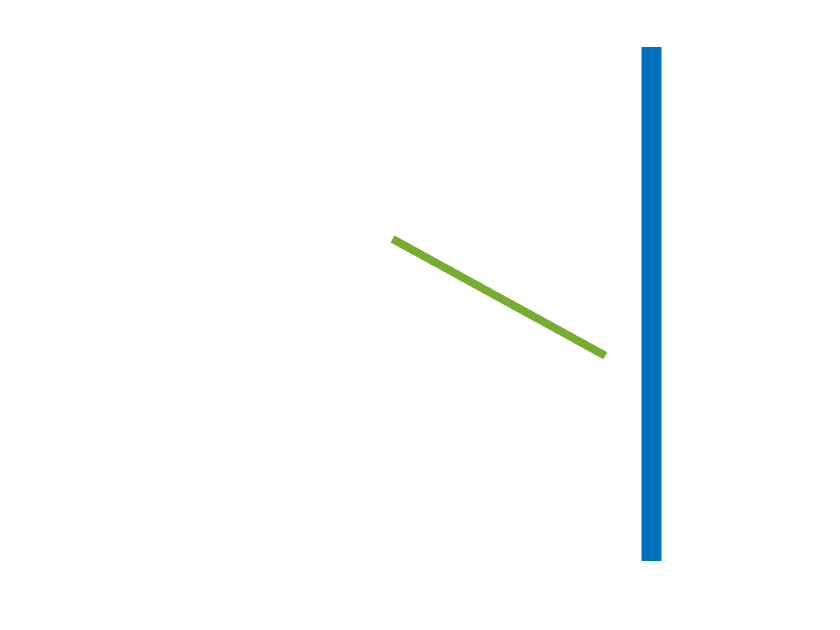

plotPressure()

### Absolute versus relative

Pressure is often referred as being absolute or relative, the absolute pressure is the pressure that was introduced previously, representing the force per unit of surface. A relative pressure is the difference of pressure between the absolute pressure and a reference pressure.


$$P_\text{absolute}=P_\text{relative} + P_\text{reference}$$


The relative pressure is often called gauge pressure.

### Units

Pressure's SI reference unit is the Pascal (Pa), named after the [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal), a French mathematician and physist from the XVII century.

  **Try. **Run the following code to create a unit system and get information about Pascals

units = symunit;
Pascals = units.Pa;
unitInfo(Pascals)


pascal - a physical unit of pressure. ['SI']

Get all units for measuring 'Pressure' by calling unitInfo('Pressure').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Pressure")


All units of dimension 'Pressure':

at - technical atmosphere
atm - standard atmosphere
Ba - barye 
bar - bar
cmH2O - centimeter of water (conventional)
cmHg - centimeter of mercury (conventional)
ftH2O - foot of water (conventional)
ftHg - foot of mercury (conventional)
inH2O - inch of water (conventional)
inHg - inch of mercury (conventional)
ksf - kip per square foot
ksi - kip per square inch
mH2O - meter of water (conventional)
mHg - meter of mercury (conventional)
mmH2O - millimeter of water (conventional)
mmHg - millimeter of mercury (conventional)
Pa - pascal ['SI']
psf - pound force per square foot
psi - pound force per square inch
pz - pieze
Torr - torr

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.


Some of the most common units of pressure are:

- mmHg (millimeter of mercury) is used in medicine to measure the blood pressure, for example a blood pressure of 120/80 means that the systolic (while the heart pump) pressure is 120 mmHg and the diastolic (while the heart is at rest in between beats) pressure is 80 mmHg.

- mH2O (meter of water) is used to design large hydraulic system such as pipeline or hydropower plant.

- atm (atmosphere) correspond to the atmospheric pressure at sea leavel (1 atm = 101325 Pa). It has been used in chemistry as standard pressure.

- bar (bar) closest multiple of Pascal to the atmosphere (1 bar = 100000 Pa), is now used to define the standard pressure in chemistry.

- psi/psf are commonly used in as empirical unit of pressure.

 **Exercise. **Use [`unitConversionFactor`](https://www.mathworks.com/help/symbolic/unitconversionfactor.html) to compute the conversion factor between bar to Pa, atm to Pa, bar to psi and atm to psi

bar2Pa = unitConversionFactor(units.bar,units.Pa)

$$bar2Pa = 100000$$

atm2Pa = unitConversionFactor(units.atm,units.Pa)

$$atm2Pa = 101325$$

bar2psi = unitConversionFactor(units.bar,units.psi)

$$bar2psi = 14.5038$$

atm2psi = unitConversionFactor(units.atm,units.psi)

$$atm2psi = 14.6959$$

 **Exercise. **Use [`rewrite`](https://www.mathworks.com/help/symbolic/rewrite.html?searchHighlight=rewrite&s_tid=srchtitle_rewrite_1) and [`baseUnits`](https://www.mathworks.com/help/symbolic/baseunits.html?s_tid=doc_ta) to first convert Pascals in the base SI units, and then into N and m.

Pascals = rewrite(Pascals, baseUnits("SI"))

$$Pascals = \frac{\mathrm{kg}}{m\,s^{2}}$$

Pascals = rewrite(Pascals, [units.m units.N])

$$Pascals = \frac{N}{m^{2}}$$

 **Reflect**. Units of pressure such as Pascals correspond to Newton per square meter, wich correspond to unit of force per unit of surface.

## Bernoulli's Principle

### Definition

The Bernoulli equation is a fundamental tool of fluid dynamisist that describes the relationship between pressure, velocity and elevation change in the fluid. This equation is named after the Swiss mathematician, Daniel Bernoulli, who first formulated it in 1738. The Bernoulli equation states that the total pressure of a fluid system is constant along a streamline:


$$P+
\frac{1}{2}\rho v^2+
\rho g z= \text{Constant} \qquad(\star)$$


where P represents the pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration and $z$the elevation. The total pressure is defined as:


$$P_\text{total} = P + \frac{1}{2}\rho v^2 + \rho g z$$


- $P$ is the static pressure, as defined in the previous section

- $\frac{1}{2}\rho v^2$ is the dynamic pressure, it is the pressure that is due to the motion of the flud

- $\rho g h$ is the hydrostatic pressure, it is the pressure that is due to the gravitational potential. This pressure is often neglected in the case of system where the fluid experience very little change of elevation or system with low density.

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the line in a flow that is tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

  **Try. **Check if density is consistent with pressure?

units = symunit;
dynamicPressureUnits = units.kg/units.m^3*(units.m/units.s)^2;
checkUnits(dynamicPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

 **Exercise. **Similarly check that the gravitational potential term's unit is consistent with a pressure units.

% Your code goes in the next line:
gravitationalPotentialUnits = 0.0;

% Check the units consistency:
checkUnits(gravitationalPotentialUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

 **Reflect**. Reflect on the similarity in between the term in equation $(\star)$ and the definition of work, kinetic energy and potential energy.

- Work: $W = \int P dV$

- Kinetic energy: $E_k = \frac{1}{2}mv^2$

- Potential energy: $E_p = mgz$

The Bernoulli equation $(\star)$ is often written in term of hydraulic head $H$:


$$\frac{P}{\rho g} + \frac{v^2}{2 g} + h = H_0=\text{Constant}
\quad\quad
(\spadesuit)$$


 **Exercise. **Express the unit of the different term in equation $(\spadesuit)$

% Your code goes in the next line:
unitHydraulicHead = units.Pa/(units.kg/units.m^3*units.m/units.s^2)

$$unitHydraulicHead = \frac{\mathrm{Pa}\,m^{2}\,s^{2}}{\mathrm{kg}}$$

% Symplify the unit expression
unitHydraulicHead = simplify(unitHydraulicHead)

$$unitHydraulicHead = m$$

### **Study Case 1**

  **Try.** Use the slider below to visualize a streamline in between point A and point B of a fluid flow with an elevation difference.

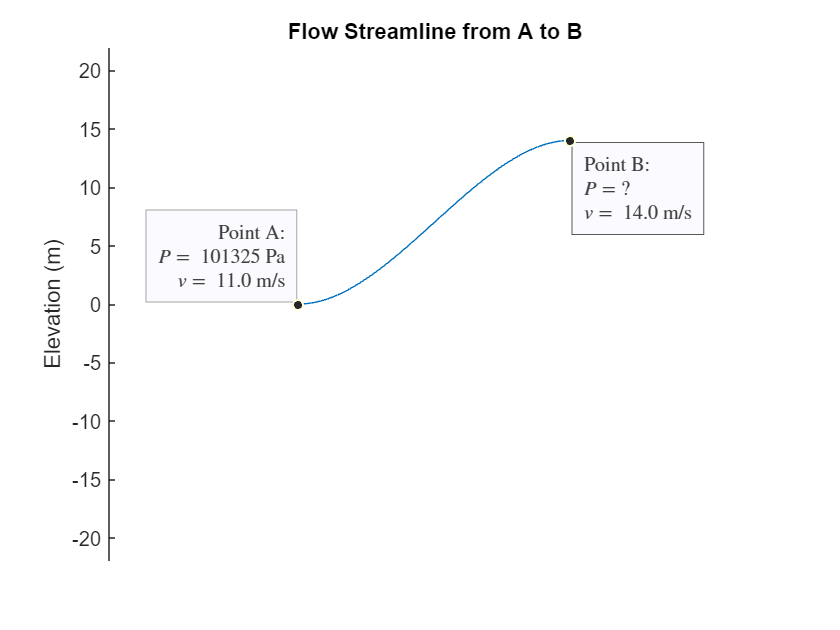

% Gather the user input:
dh = 14;
velocityA = 11;
velocityB = 14;
rho = 1000;
plotStreamline(dh, velocityA, velocityB)

 **Exercise.** Considering the pressure at point B as our unknown, define the total pressure at point A and point B

% Define the unknown
syms P_b

% Add the units:
dh = dh*units.m;
velocityA = velocityA*units.m/units.s;
velocityB = velocityB*units.m/units.s;
rho = rho*units.kg/units.m^3;
g = 9.81 * units.m / units.s^2;

% Your code goes here:
totalPressureA = 101325*units.Pa + 0.5*rho*velocityA^2 + rho*g*0.0;
totalPressureB = P_b + 0.5*rho*velocityB^2 + rho*g*dh

$$totalPressureB = P_{b}+235340\,\frac{\mathrm{kg}}{m\,s^{2}}$$

 **Exercise.**  Considering equation $(\star)$, solve for the pressure at point B

P_b = solve(totalPressureA==totalPressureB, P_b);

  **Try.** You can simplify the results:

 P_b = simplify(P_b)

$$P\_b = -73515\,\frac{\mathrm{kg}}{m\,s^{2}}$$

### **Application: Converging Pipe Flow**

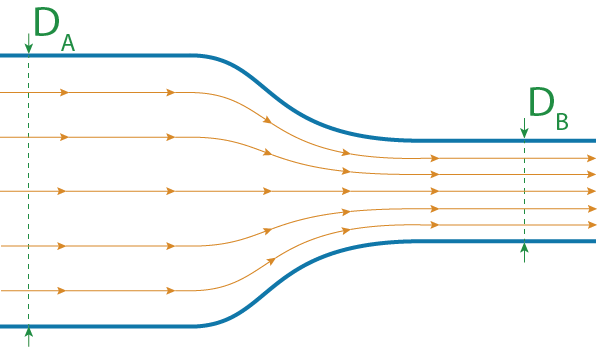

Consider a convergent of upstram diameter $D_A$ and downstream diameter $D_B$, the inflow velocity is $V_A$ and the fluid is considered to be incompressible.

 **Exercise.** Based on the previous parameter, calculate the downstream velocity of the fluid $V_b$

 syms D_A D_B v_A rho P_A P_B
 v_B = (D_A/D_B)^2*v_A

 **Exercise.** Calculate the upstream and downstream total pressure

upstreamTotalPressure = P_A + 0.5*rho*v_A^2
downstreamTotalPressure = P_B + 0.5*rho*v_B^2

  **Try.** Solve the equation for $\Delta P = P_B - P_A$

DP = solve(upstreamTotalPressure==downstreamTotalPressure,P_B) - P_A
DP = simplify(DP)

 **Reflect**. Knowing that $D_A > D_B$ should we expect the pressure to increase or decrease along the converging pipe? This counter-intuitive results is called Bernoulli's principle.

### **Application: Pitot tube**

Pitot tubes are apparatus that measure the flow velocity. It is commonly used on aircraft to measure the airspeed and the water speed for boats.

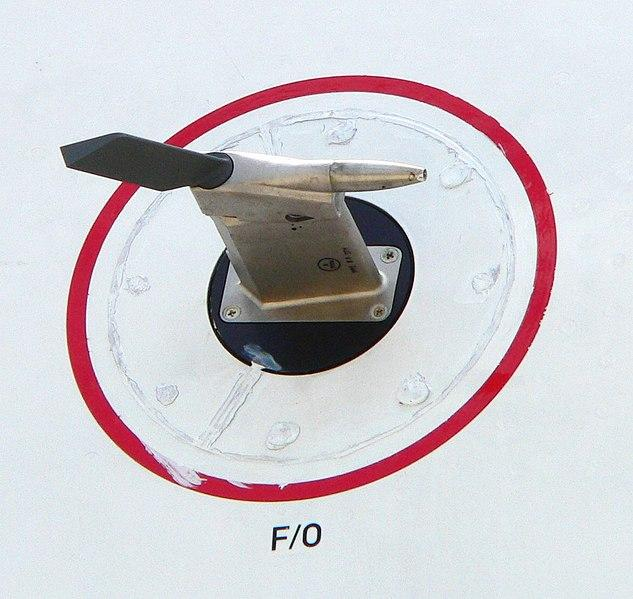

An Airbus A380's pitot tube, [wikimedia](https://commons.wikimedia.org/wiki/File:Airspeed_p1230157.jpg)

There is multiple type of Pitot tube, in this section we will study a Pitot-static tube, which present two opening, one in the front and one on the side. The tube is oriented directly facing the 

We also define the stagnation pressure, which is the pressure that the fluid would have if it came to a full stop:


$$ P_\text{static} + \frac{1}{2}\rho v^2 = P_\text{stagnation} + \frac{1}{2}\rho 0^2$$


Therefore,


$$P_\text{stagnation} = P_\text{static} + \frac{1}{2}\rho v^2$$


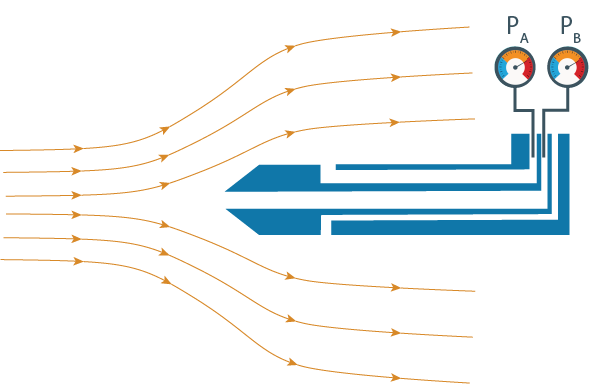

 **Exercise.** Identify the pressure measured by gauge A and gauge B.

checkPressurePitot(GaugeA="Static",GaugeB="Stagnation");
 

 **Exercise. Based on your answer to the previous question, what does the difference **$P_b-P_a$ represents?

checkPressureDifferencePitot("None");
 

 **Exercise.** Express the free-stream velocity `freeStreamVelocity` as a function of $\Delta p = p_t - p_s$

% Declare the parameter of the problem:
syms u(deltap) rho
rho = 1.14;

% Your code goes here:
freeStreamVelocity(deltap) = 0.0;

% Plot the results:
figure
fplot(freeStreamVelocity,[0 10000],LineWidth=2)
title("Pitot-static - Pressure/Velocity corelation")
xlabel("Pressure difference (Pa)")
ylabel("Air velocity (m/s)")

### **Application: Lift generation around airfoil**

In this section we will be studying the lift generation by a NACA-2412 airfoil. This airfoil presents a 2% camber at with the max camber at 40% of the chords and 12% thickness. 

[~,~,~] = NACA4(12,2,40);

For more information about NACA airfoil and the NACA4 function run the following command in your command window:

We consider that the plane using this airfoil is flying at a cruise speed of 135 kt (knots).

  **Try.** Run the following code to create to convert the cruise speed in (m/s).

units = symunit;
cruiseSpeed = 135 * units.kts;
cruiseSpeed = unitConvert( cruiseSpeed, units.m/units.s)

The upstream velocity is considered to be equal to the atmospheric pressure (101325 Pa) and the air density is considered to be 1.14 kg/m3. 

upstreamPressure = 101325*units.Pa;
rhoAir = 1.14*units.kg/units.m^3;

  **Try.** Define the velocity along the upper and lower surface

upperVelocity = 94*units.m/units.s;
lowerVelocity = 47*units.m/units.s;

 **Exercise. **using Bernoulli's principle, compute the pressure along the upper and lower surface.

% Write your code here:
upperPressure = simplify(upstreamPressure + 1/2*rhoAir*cruiseSpeed^2 - 1/2*rhoAir*upperVelocity^2);
lowerPressure = simplify(upstreamPressure + 1/2*rhoAir*cruiseSpeed^2 - 1/2*rhoAir*lowerVelocity^2);
pressureDifference = upperPressure - lowerPressure

  **Try. **Set a larger velocity along the lower surface than along the upper surfaces, 

pressureDifference

 **Exercise. **Should the pressure difference be positive or negative to generate an upward "lift" force along the airfoil?

checkPressureDifferenceSign("Negative")

## Further Exploration

## Helper Functions

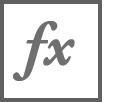**plotStreamline**`(dh, v1, v2, rho)`

- `dh`

- `v1`

- `v2`

- `rho`

function plotStreamline(dh, v1, v2)
arguments
    dh (1,1) {mustBeReal,mustBeInRange(dh,-20,20)} = 0
    v1 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v1,0.0)} = 0.0
    v2 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v2,0.0)} = 0.0
end    

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dh*(2*xl.^3-3*xl.^2);

    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    s = scatter(ax,0,0,30,'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point A:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = $",  [101325], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$v = $", [v1], "%10.1f m/s");
    d = datatip(s);
    d.Interpreter = "latex";
    d.Location = "northwest";
    hold on

    % Plot B:
    s = scatter(ax,1,dh, 'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point B:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = ?$",  [], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$v = $", [v2], "%10.1f m/s");
    d = datatip(s);
    d.Location = "southeast";
    d.Interpreter = "latex";
    
    
    % Plot Free Path:
    plot(ax,xl,yl)
    hold off

    % Set plot limit, title, etc.:
    xlim([-0.7 1.7])
    ylim([-22 22])
    title("Flow Streamline from A to B")
    ylabel("Elevation (m)")
    ax.XAxis.Visible = "off";
    
end

function plotPressure()
    figure
    ax = axes;
    axis off
    xlim(ax,[0 1.2])
    ylim(ax,[-1 1])
    l = line(ax,[1 1],[-1 1],"LineWidth",10);
    dt = 0.1;
    x = [0 2*rand-1];
    v = [1 2*rand-1] - x;
    v = v / norm(v);
    
    h = animatedline(ax,'MaximumNumPoints',7,"LineWidth",4,"Color",ax.ColorOrder(5,:));
    addpoints(h, x(1), x(2))
    for i = 1:200
        if l.Color == ax.ColorOrder(3,:)
            l.Color = ax.ColorOrder(1,:);
        end
        x = x + dt*v;
        if x(1) > 1.0
            x(1) = 1.0;
            v(1) = -v(1);
            l.Color = ax.ColorOrder(3,:);
        end
        if x(1) < 0.0
            x = [0 2*rand-1];
            v = [1 2*rand-1] - x;
            v = v / norm(v);
            clearpoints(h)
        end
        addpoints(h, x(1),x(2)) 
        drawnow
    end
end

function checkPressureDifferenceSign(answer)
    arguments
        answer (1,1) string {mustBeMember(answer,{'None','Positive','Negative'})}
    end
    switch answer
        case "None"
            warning("Please select either positive or negative.")
        case "Positive"
            warning("XXX")
        case "Negative"
            disp("Good job! A negative pressure difference would create an force on the airfoil called lift.")
            [~,~,~] = NACA4(12,2,40);
            legend off
            annotation('arrow',[0.5 0.5],[0.5 0.7],LineWidth=3)
            annotation('textbox',[0.5 0.6 0.2 0.2],String="$\vec{F}$",Interpreter="latex",VerticalAlignment="bottom",LineStyle="none")
    end
end

function checkPressurePitot(opts)
    arguments
        opts.GaugeA (1,1) string {mustBeMember(opts.GaugeA,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
        opts.GaugeB (1,1) string {mustBeMember(opts.GaugeB,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
    end

    if (opts.GaugeA == "Static" && opts.GaugeB == "Stagnation")
        disp("Good job! You have identified the pressure correctly.")
    elseif (opts.GaugeA == "Static")
        warning("You misidentified the pressure at gauge B, try again!")
    elseif (opts.GaugeB == "Stagnation")
        warning("You misidentified the pressure at gauge A, try again!")
    else
        warning("You misidentified both pressure, try again!")
    end

end

function checkPressureDifferencePitot(answer)
    arguments
        answer (1,1) string {mustBeMember(answer,{'None','Static','Stagnation','Dynamic'})}
    end

    switch answer
        case "None"
            warning("Please select one of the options in the drop-down control.")
        case "Static"
            warning("The gauge A is already measuring the static pressure, so the difference between A and B can not be static pressure.")
        case "Stagnation"
            warning("The gauge B is already measuring the stagnation pressure, so the difference between A and B can not be static pressure.")
    end
    

    if answer == "Dynamic"
        disp("Good job! The pressure difference is the dynamic pressure.")
    end
end

[⇦ Return to the navigation page](matlab:open('./Overview.html'))

Copyright 2023 The MathWorks™, Inc